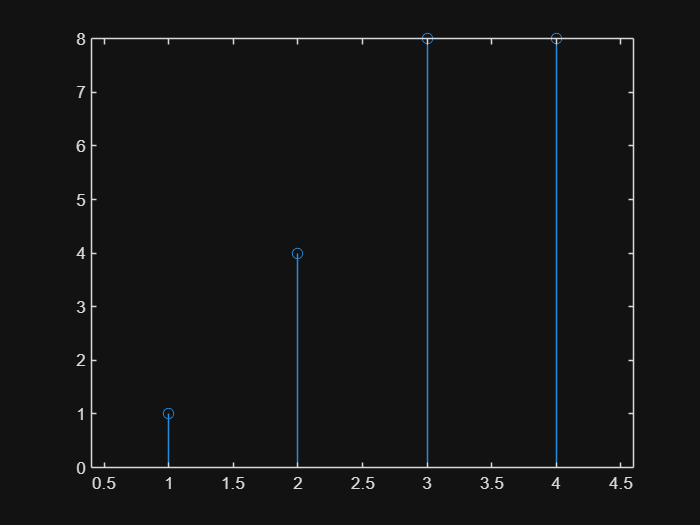

%%To compute the response of a discrete LTI system within put sequence x(n) and impulse response h(n) by 
%%using linear convolution without using the inbuilt conv function. Verify your program using the conv function 
%%for sequences x = [1, 2] and h = [1, 2, 4].

x = [1 2];
h = [1 2 4];

y = conv(x, h);
stem(y);

function y = linear_conv(x, h)
    n = length(x);
    m = length(h);
    
    y = zeros(1, n + m - 1);
    
    for i = 1:n
        for j = 1:m
            y(i + j - 1) = y(i + j - 1) + x(i) * h(j);
        end
    end
end

function y = circular_conv(x, h)
    N = max(length(x), length(h));
    
    % Zero padding
    x = [x zeros(1, N - length(x))];
    h = [h zeros(1, N - length(h))];
    
    y = zeros(1, N);
    
    for n = 1:N
        for k = 1:N
            index = mod(n - k, N);
            y(n) = y(n) + x(k) * h(index + 1);
        end
    end
end

x=[1 2];
h=[1 2 4];

y = linear_conv(x, h);
stem(y);

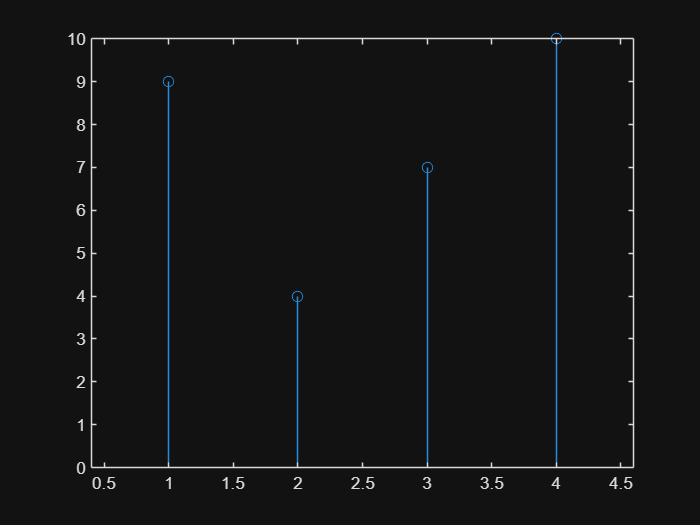

 x = [1,2,3,4];
 h = [1,2];

 y = cconv(x, h, 4);
 stem(y);


y = circular_conv(x, h);
stem(y);